SHOW DEFECT DISTRIBUTION LOAD DATA

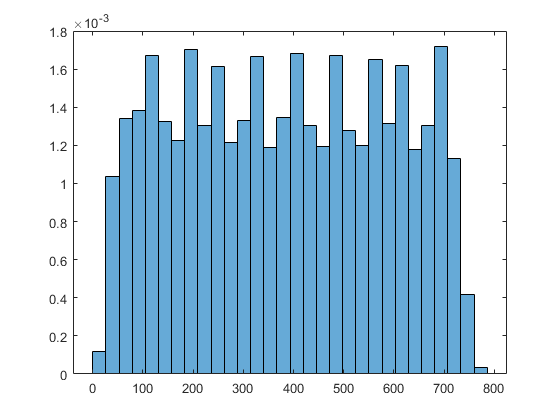

clearvars
PC_path = 'C:\Users\victo\Google Drive\';   % HP notebook
% PC_path = 'C:\Users\vici\Google Drive\';    % Curie PC
% PC_path = 'D:\GD\';                         % RSIP notebook
folder_path = 'Curie\DESKTOP\HT1080\';

set_name = {'pDefect_angle300',...
            'pDefect_angle200',...
            'pDefect_angle400',...
            'pDefect_angle600',...
            'pDefect_angle800'};

        
load([PC_path, folder_path, set_name{5}, '.mat']);
% PdefPOS = PdefPOS_free;
emptyTF = cellfun(@isempty,PdefPOS); %check for empty cells
fileY = ~emptyTF; %sum(~emptyTF)
PdefPOS_1 = PdefPOS(fileY);
QQ = [];
for j = 1:length(PdefPOS_1)
    emptyTF = cellfun(@isempty,PdefPOS_1{j}); %check for empty cells
    s9 = ~emptyTF; %sum(~emptyTF)
    QQ{j,1} = cell2mat(PdefPOS_1{j}(s9));
end

Q = cell2mat(QQ);
% histogram(Q(:,1),30); 

dw = 60; % border width
px_sizeOP = .74*3;
max_xpos = max(Q(:,1));

figure();
histogram(Q(:,1),30,'Normalization', 'PDF');  hold off

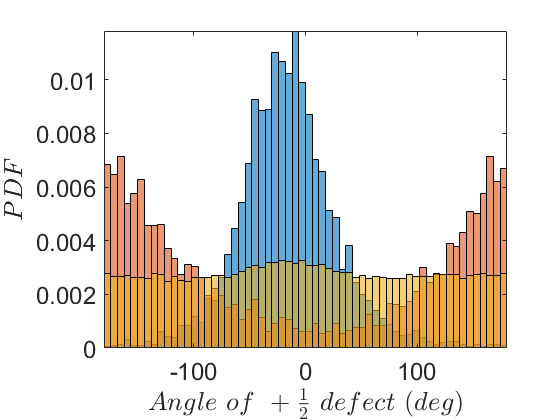


figure(floor(width(1)));
histogram(Q(Q(:,1)<dw,3),60,'Normalization', 'PDF');  hold on
histogram(Q(Q(:,1)>(max_xpos-dw-.1*dw),3),60,'Normalization', 'PDF');  hold on
histogram(Q(:,3),60,'Normalization', 'PDF');  hold off
axis([-180 180 0 inf]); set(gca,'Fontsize',18); 
ylabel('$ PDF $','Interpreter','latex','FontSize',28);
xlabel('$Angle\ of\ + \frac{1}{2}\ defect\ (deg)$','Interpreter','latex','FontSize',28);

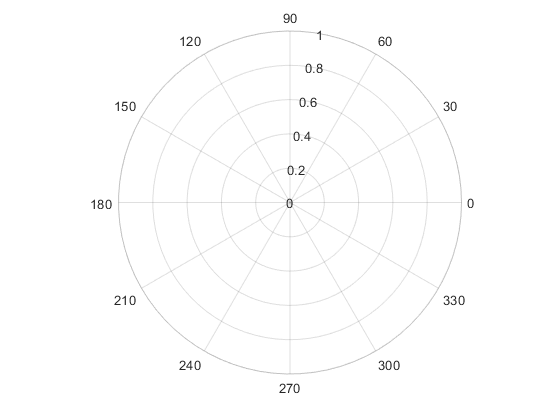

figure(floor(width(1))+1);
polarhistogram(Q(Q(:,1)<dw,3)/180*pi,60,'Normalization', 'PDF');  hold on
polarhistogram(Q(Q(:,1)>(max_xpos-dw-.1*dw),3)/180*pi,60,'Normalization', 'PDF');  hold on
polarhistogram(Q(:,3)/180*pi,60,'Normalization', 'PDF');  hold off

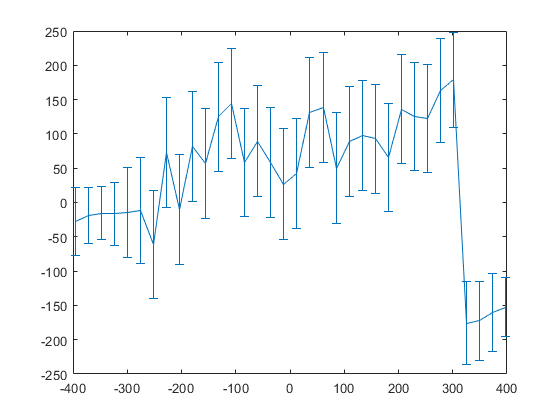


Q = sortrows(Q,1);
reduce = round(0.03*width(1));
xpos = reduce*round(Q(:,1)/reduce)- (max(Q(:,1))+min(Q(:,1)))/2;
angle  = Q(:,3)*pi/180;
[U_xpos,~,idx]  = unique(xpos);
N = histc(xpos, U_xpos); % repetition number
U_xpos_angle = [U_xpos, accumarray(idx, angle,[],@circ_mean), accumarray(idx,angle,[],@circ_std)];% ./sqrt(N)


x_pos_plt = U_xpos_angle(:,1);
ang_plt = 180/pi*U_xpos_angle(:,2);
% ang_plt(ang_plt<0) = ang_plt(ang_plt<0)+360;
ang_std_plt = 180/pi*U_xpos_angle(:,3);

figure(11); errorbar(x_pos_plt,ang_plt,ang_std_plt);

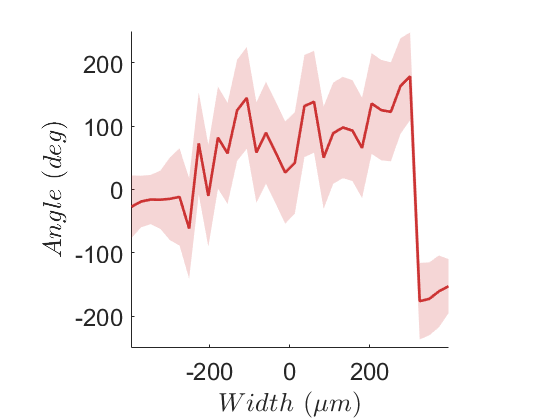

figure
% [llB, bB] = boundedline(x_pos_plt,ang_plt,ang_std_plt,'alpha');
[llB, bB] = boundedline(U_xpos_angle(:,1),180/pi*U_xpos_angle(:,2),180/pi*U_xpos_angle(:,3),'alpha');
llB.LineWidth = 2;llB.Color = [0.8,0.2,0.2];bB.FaceColor = [0.8,0.2,0.2];bB.FaceAlpha = .2;
set(gca,'Fontsize',18);
ylabel('$Angle \ (deg)$','Interpreter','latex','FontSize',28);
xlabel('$ Width \ (\mu m) $','Interpreter','latex','FontSize',24);
axis square tight
ylim([-250,250])